clc
close
clear

% 加载状态方程及传递函数
run('Modeling.m')
% sys_ss : 动力学建模得到的系统状态方程
% sys_tf : 动力学建模得到的系统传递函数
% sys_ss2tf : 系统状态方程转化为传递函数
% sys_tf2zpk_pend : 传递函数转化为零极点形式(摆杆)
% sys_tf2zpk_cart : 传递函数转化为零极点形式(推车)
% sys_ss2zpk : 系统状态方程转化为零极点形式

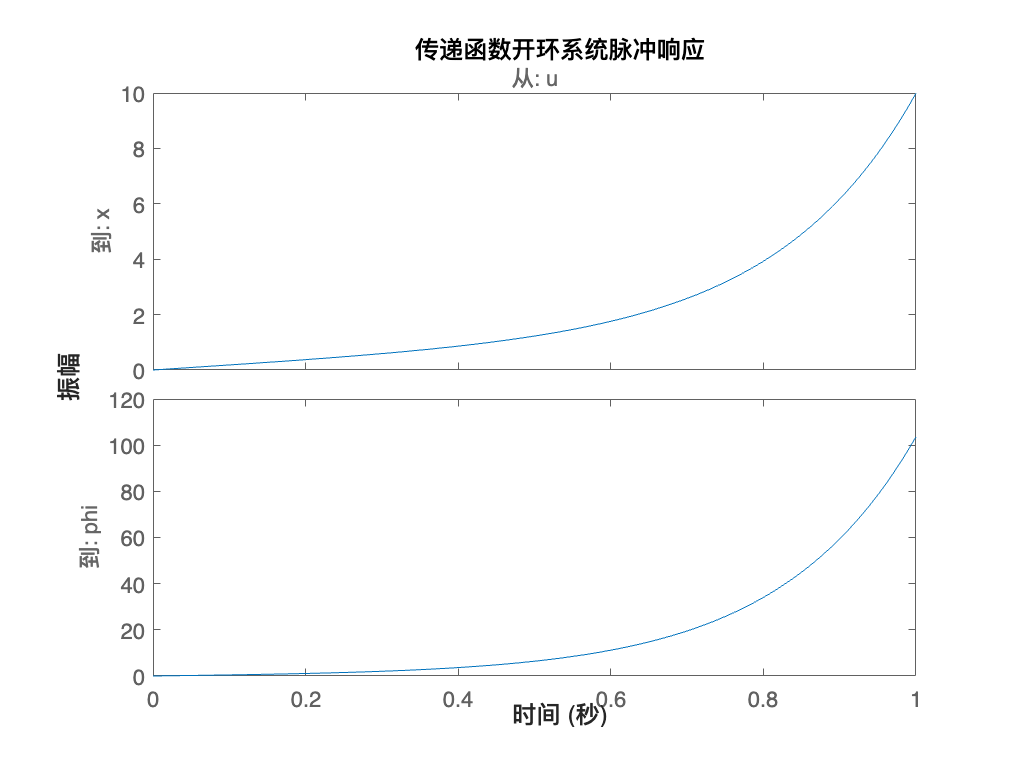

% 开环系统响应曲线分析

% 脉冲响应表现为推车无限向右移动 且仅对小角度有效果
t = 0:0.01:1;
impulse(sys_tf,t);
title('传递函数开环系统脉冲响应')

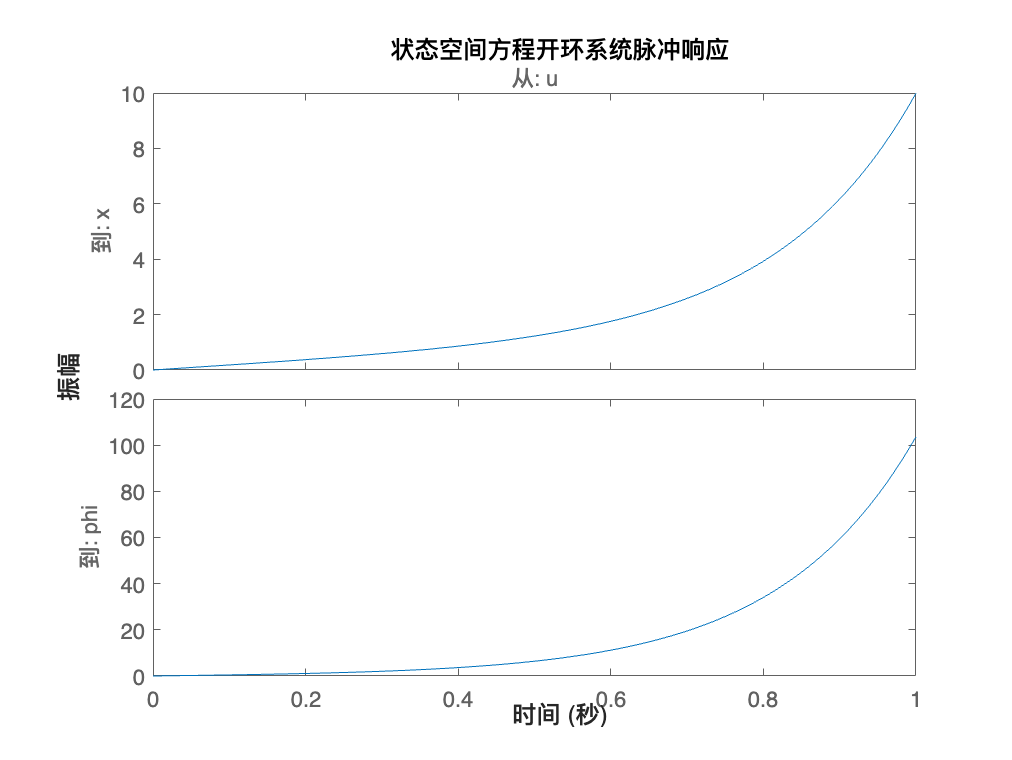

impulse(sys_ss,t);
title('状态空间方程开环系统脉冲响应')

% 检查系统零极点或特征值
[z_tf_cart , p_tf_cart] = zpkdata(P_cart,'v')

z_tf_cart =     4.9497
   -4.9497


p_tf_cart =          0
    5.5651
   -5.6041
   -0.1428


[z_tf_pend , p_tf_pend] = zpkdata(P_pend,'v')

z_tf_pend = 0

p_tf_pend =     5.5651
   -5.6041
   -0.1428


[z_ss , p_ss] = zpkdata(sys_ss,'v')

z_ss = 2×1 cell 数组
    {2×1 double  }
    {[1.7936e-16]}


p_ss = 2×1 cell 数组
    {4×1 double}
    {3×1 double}



lambda = eig(A)

lambda =          0
   -0.1428
   -5.6041
    5.5651


% 从特征值和极点均能看出来，系统不稳定，与脉冲响应曲线结果一致

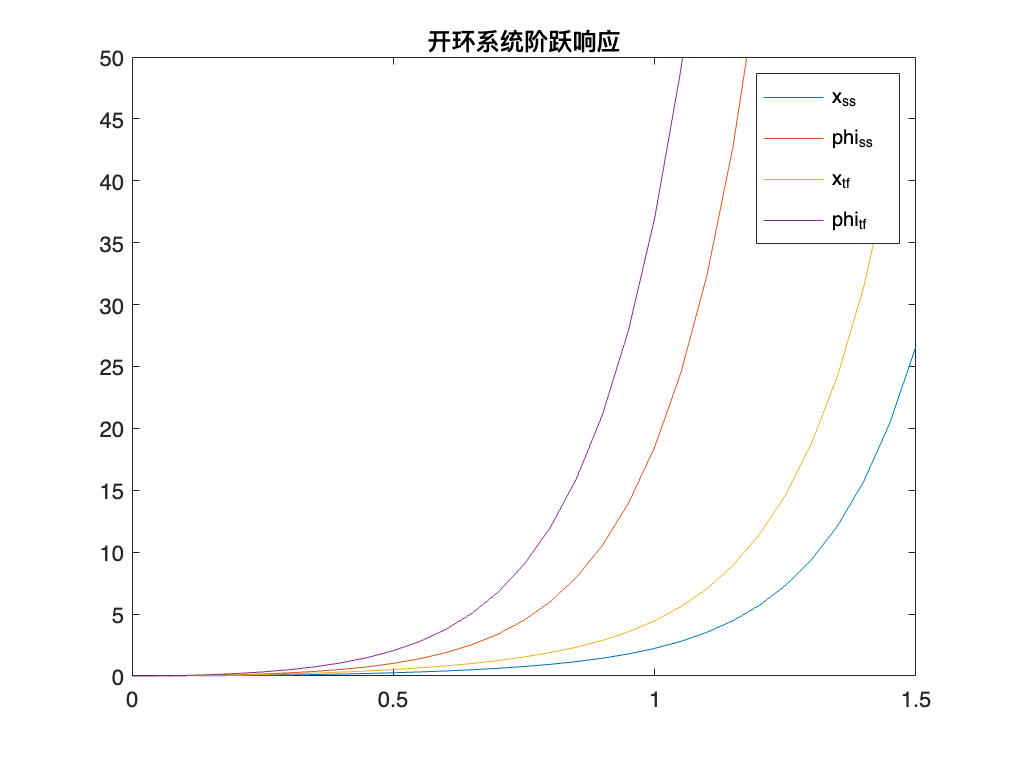

% 利用lsim模拟LTI模型对于任意输入的响应
% 输入为1N的阶跃信号
close
t = 0:0.05:10;
u = ones(size(t));
[y_ss,t] = lsim(sys_ss,u,t);
plot(t,y_ss)
hold on 
[y_tf,t] = lsim(sys_tf,2*u,t);
plot(t,y_tf)
legend('x_ss','phi_ss','x_tf','phi_tf')
axis([0 1.5 0 50])
title('开环系统阶跃响应')


% 识别重要特征
step_ss_info = lsiminfo(y_ss,t);
cart_ss_info = step_ss_info(1)

cart_ss_info = 包含以下字段的 struct :
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 8.7918e+21
          MaxTime: 10


pend_ss_info = step_ss_info(2)

pend_ss_info = 包含以下字段的 struct :
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 1.0520e+23
          MaxTime: 10



step_tf_info = lsiminfo(y_tf,t);
cart_tf_info = step_tf_info(1)

cart_tf_info = 包含以下字段的 struct :
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 1.7584e+22
          MaxTime: 10


pend_tf_info = step_tf_info(2)

pend_tf_info = 包含以下字段的 struct :
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 2.1041e+23
          MaxTime: 10
